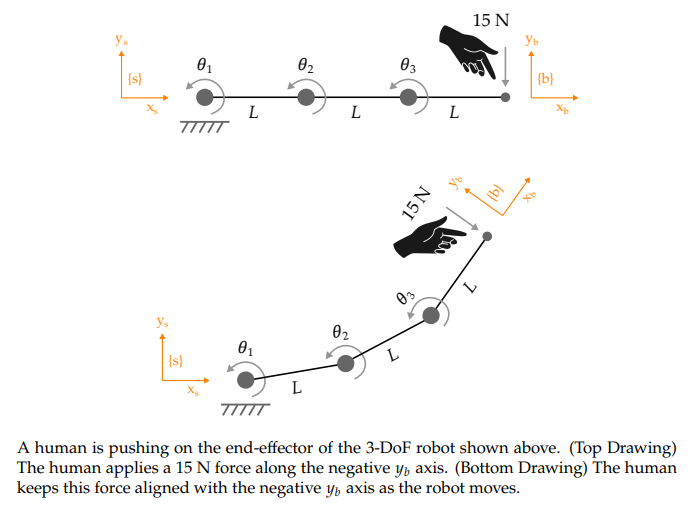

**What wrench does the robot need to apply at the end-effector to maintain static equilibrium?**

**Solution**: Opposite force of $+15N$ over positive y-axis. 

Thus the wrench required is provided below with the formulae: $F_b =\left\lbrack \begin{array}{c}
m_b \\
f_b 
\end{array}\right\rbrack$ and moment $m_b$ is zero as the force is directly applied over the body frame.

clc
clear

syms theta1 theta2 theta3 real


% Opposite force of +15 N over positive y-axis
% Thus the wrench required is provided below with the formulae: Fb = [mb;fb] and moment is zero as the force is directly applied over the body frame

Fb = [0;0;0;0;15;0];

**Case 1:** Let 𝐿 = 1 and let 𝜃 = [0, 𝜋/4, 𝜋/4] ' . Find the joint torques needed to balance out the force applied by the human. 

**Case 2:** Let 𝐿 = 1 and let 𝜃 = [0, 𝜋/8, 0] ' . Find the joint torques needed to balance out the force applied by the human

theta = [theta1;theta2;theta3];


omega = [0;0;1];

q1 = [0;0;0];
q2 = [1;0;0];
q3 = [2;0;0];

S1 = [omega; -cross(omega, q1)];
S2 = [omega; -cross(omega, q2)];
S3 = [omega; -cross(omega, q3)];

S_eq = [S1, S2, S3];   
M = [eye(3), [3;0;0]; 0 0 0 1];

% T with initial joint positions
T_0 = simplify(expand(fk(M, S_eq, theta)))

$$T\_0 = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{1}+\theta_{2}\right)+\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & \sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)+\sin\left(\theta_{1}+\theta_{2}\right)+\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_0 = T_0(1:3, 1:3);
JS = simplify(expand(JacS(S_eq, theta))) %Space Jacobian

$$JS = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1\\ 0 & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}+\theta_{2}\right)+\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}+\theta_{2}\right)-\cos\left(\theta_{1}\right)\\ 0 & 0 & 0 \end{array}\right)$$

Jb = simplify(expand(adjointM(inv(T_0))*JS)) %Body Jacobian

$$Jb = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1\\ \sin\left(\theta_{2}+\theta_{3}\right)+\sin\left(\theta_{3}\right) & \sin\left(\theta_{3}\right) & 0\\ \cos\left(\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{3}\right)+1 & \cos\left(\theta_{3}\right)+1 & 1\\ 0 & 0 & 0 \end{array}\right)$$

J_geometric = simplify(expand([R_0, zeros(3); zeros(3), R_0] * Jb)) %Geometric Jacobian

$$J\_geometric = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1\\ -\sigma_{1}-\sin\left(\theta_{1}+\theta_{2}\right)-\sin\left(\theta_{1}\right) & -\sigma_{1}-\sin\left(\theta_{1}+\theta_{2}\right) & -\sigma_{1}\\ \sigma_{2}+\cos\left(\theta_{1}+\theta_{2}\right)+\cos\left(\theta_{1}\right) & \sigma_{2}+\cos\left(\theta_{1}+\theta_{2}\right) & \sigma_{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$


% Fs calculation: 
Fs = simplify(expand(adjointM(inv(T_0)))'*Fb)

$$Fs = \left(\begin{array}{c} 0\\ 0\\ 15\,\cos\left(\theta_{2}+\theta_{3}\right)+15\,\cos\left(\theta_{3}\right)+15\\ -15\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 15\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 0 \end{array}\right)$$


% symbolic tau calculation
tau = simplify(expand(JS'*Fs))

$$tau = \left(\begin{array}{c} 15\,\cos\left(\theta_{2}+\theta_{3}\right)+15\,\cos\left(\theta_{3}\right)+15\\ 15\,\cos\left(\theta_{3}\right)+15\\ 15 \end{array}\right)$$


% CASE 1
Case1_tau = double(subs(tau,[theta1,theta2,theta3],[0,pi/4,pi/4]))

Case1_tau =    25.6066
   25.6066
   15.0000



% CASE 2
Case2_tau = double(subs(tau,[theta1,theta2,theta3],[0,pi/8,0]))

Case2_tau =    43.8582
   30.0000
   15.0000


Let ∥𝜏∥ be the magnitude (i.e., the length) of the joint torque vector. 

    • Find a joint position 𝜃 that maximizes ∥𝜏∥ 

    • Find a joint position 𝜃 that minimizes ∥𝜏∥ 

% ||tau||
magnitude_tau = simplify(expand(norm(tau)))

$$magnitude\_tau = \frac{15\,\sqrt{2}\,\sqrt{\cos\left(2\,\theta_{3}\right)+4\,\cos\left(\theta_{3}\right)+2\,{\left(\cos\left(\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{3}\right)+1\right)}^{2}+5}}{2}$$



% Maximum ||tau|| with theta1 = theta2 = theta3 = 0
% or theta1 = 90 degrees, theta2 = 0, theta3 = 0
Max__mag_tau = double(subs(magnitude_tau,[theta1,theta2,theta3],[0,0,0]))

Max__mag_tau = 56.1249

% f = (15*sqrt(sym(2))*sqrt(cos(2*theta3) + 4*cos(theta3) + 2*(cos(theta2 + theta3) + cos(theta3) + 1)^2 + 5))/2

% Minimum ||tau|| with theta1 = 90 degrees, theta2 = 90 degrees, theta3 = 180 degrees
Min_mag_tau = double(subs(magnitude_tau,[theta1,theta2,theta3],[-pi/2,pi/2,pi]))

Min_mag_tau = 15


% Verifying the optimal results of all theta values for maximum and minimum
% evaluation of the magnitude of joint torque values:

fprintf(['Verifying results for maximum and minimum magnitude of tau with' ...
    'optimal theta values:\n']);

Verifying results for maximum and minimum magnitude of tau withoptimal theta values:



% Define the objective function to maximize Magnitude_tau
objectiveFunction_Max = @(theta) -double(norm(subs(magnitude_tau, [theta1, theta2, theta3], double(theta))));
% Define the objective function to mainimize Magnitude_tau
objectiveFunction_Min = @(theta) double(norm(subs(magnitude_tau, [theta1, theta2, theta3], double(theta))));

% Define initial guess for thetas
x0 = [pi/4, pi/4, pi/4];

% Define bounds on thetas
lb = [0, 0, 0];
ub = [pi, pi, pi];

% Set up the optimization options
options = optimoptions('fmincon', 'Display', 'iter'); % Display optimization process

% Solve the optimization problem to find maximum magnitude_tau
[xMax, fMax] = fmincon(objectiveFunction_Max, x0, [], [], [], [], lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4   -3.919689e+01    0.000e+00    9.966e+00
    1       8   -5.609177e+01    0.000e+00    1.272e+01    1.060e+00
    2      12   -5.608346e+01    0.000e+00    9.967e-02    6.658e-02
    3      16   -5.611481e+01    0.000e+00    2.462e-01    1.043e-01
    4      20   -5.612178e+01    0.000e+00    3.808e-02    4.584e-02
    5      24   -5.612351e+01    0.000e+00    3.991e-02    9.528e-03
    6      28   -5.612379e+01    0.000e+00    8.705e-03    8.547e-03
    7      32   -5.612387e+01    0.000e+00    2.934e-03    8.270e-03
    8      36   -5.612392e+01    0.000e+00    7.059e-03    2.686e-02
    9      40   -5.612394e+01    0.000e+00    8.432e-03    1.066e-01
   10      44   -5.612391e+01    0.000e+00    5.702e-03    2.502e-01
   11      48   -5.612387e+01    0.000e+00    2.014e-03    3.047e-01
   12      52   -5.612386e+01    0.000e+00    1


% Display the results (Maximum)
fprintf('Maximum Magnitude_tau: %f\n', abs(-fMax)); % Negate the value back to the original form

Maximum Magnitude_tau: 56.124860


fprintf('Optimal values for theta1, theta2, and theta3: %f, %f, %f\n', rad2deg(xMax(1)), rad2deg(xMax(2)), rad2deg(xMax(3)));

Optimal values for theta1, theta2, and theta3: 89.992386, 0.012731, 0.007796



% Solve the optimization problem to find minimum magnitude_tau
[xMin, fMin] = fmincon(objectiveFunction_Min, x0, [], [], [], [], lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    3.919689e+01    0.000e+00    2.214e+01
    1       8    1.626950e+01    0.000e+00    6.725e+00    2.648e+00
    2      13    1.531488e+01    0.000e+00    2.331e+00    6.207e-01
    3      17    1.500300e+01    0.000e+00    4.903e-01    2.868e-01
    4      21    1.501394e+01    0.000e+00    4.960e-01    2.316e-01
    5      25    1.501695e+01    0.000e+00    9.723e-02    9.207e-02
    6      29    1.500593e+01    0.000e+00    1.378e-01    1.109e-01
    7      33    1.500462e+01    0.000e+00    2.021e-02    8.398e-03
    8      37    1.500207e+01    0.000e+00    2.610e-02    5.367e-02
    9      41    1.500075e+01    0.000e+00    2.970e-02    5.741e-02
   10      45    1.500030e+01    0.000e+00    1.618e-02    3.999e-02
   11      49    1.500013e+01    0.000e+00    7.487e-03    2.953e-02
   12      53    1.500007e+01    0.000e+00    2


% Display the results (Minimum)
fprintf('Minimum Magnitude_tau: %f\n', abs(-fMin)); % Negate the value back to the original form

Minimum Magnitude_tau: 15.000000


fprintf('Optimal values for theta1, theta2, and theta3: %f, %f, %f\n', rad2deg(xMin(1)), rad2deg(xMin(2)), rad2deg(xMin(3)));

Optimal values for theta1, theta2, and theta3: 90.001144, 90.817724, 179.176356
